% =========================================================================
% === 车辆速度数据多项式拟合与可视化程序 (已修正) ===
% =========================================================================

% --- 1. 初始化环境 ---
% 清理工作区、命令窗口和关闭所有图形窗口
clearvars;
clc;
close all;

% --- 2. 读取数据 ---
% 定义您的CSV文件名
filename = 'car_speed_data.csv';

% 使用 readtable 函数读取数据
try
    data_table = readtable(filename);
catch
    error('无法读取文件 "%s"。请确保该文件与您的MATLAB脚本在同一个文件夹下。', filename);
end


% 从表格中提取速度数据
% =========================================================================
% === 核心修正：使用列的数字索引(第4列)来避免因MATLAB版本不同导致列名识别错误的问题 ===
speed = data_table{:, 4}; 
% =========================================================================

% 创建一个与数据点数量相对应的 x 轴 (数据点索引)
time = (1:height(data_table))';

% --- 3. 多项式拟合 ---
% 定义多项式的阶数。您可以调整这个数值来观察不同的拟合效果。
poly_degree = 22;

% 使用 polyfit 函数进行多项式拟合
p = polyfit(time, speed, poly_degree);

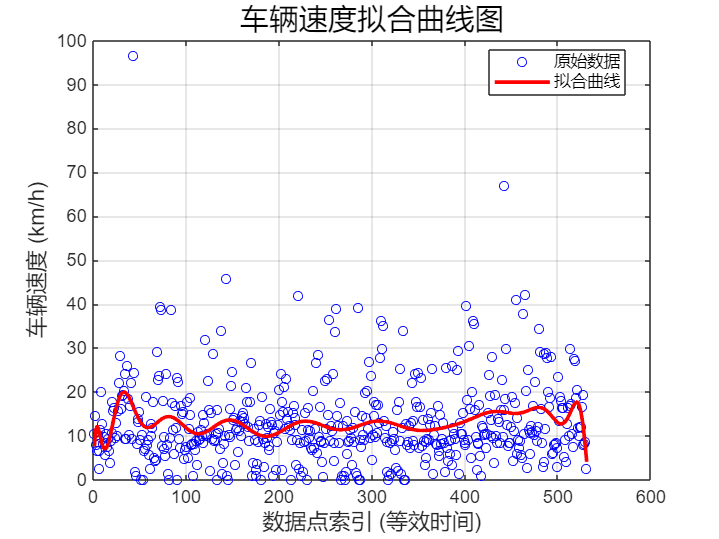


% 使用 polyval 函数根据拟合系数计算出每个时间点上的拟合值
fitted_speed = polyval(p, time);

% --- 4. 绘图 ---
% 创建一个新的图形窗口
figure;

% 绘制原始数据点 (蓝色圆点)
plot(time, speed, 'bo', 'DisplayName', '原始数据', 'MarkerSize', 5);

% 在同一个图上继续绘制
hold on;

% 绘制拟合曲线 (红色实线)
plot(time, fitted_speed, 'r-', 'DisplayName', '拟合曲线', 'LineWidth', 2);

% 停止在同一个图上绘制
hold off;

% --- 5. 美化图形 ---
% 添加标题
title('车辆速度拟合曲线图', 'FontSize', 16);

% 添加 x 轴和 y 轴的标签
xlabel('数据点索引 (等效时间)', 'FontSize', 12);
ylabel('车辆速度 (km/h)', 'FontSize', 12);

% 显示图例，并设置最佳显示位置
legend('show', 'Location', 'best');

% 添加网格线，方便观察
grid on;


% 设置坐标轴范围，避免极端值影响整体观察
% ylim([0, 100]); % 您可以取消这一行的注释并设置一个合适的Y轴上限，比如100 km/h

% --- 程序结束 ---
disp('程序运行完毕，图形已生成。');

程序运行完毕，图形已生成。
